# A Rough Estimation Contour for S_EI and S_IE

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = '/home/zx555/Documents/MATLAB/NYU-Vision-main/MFModel Code'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])

N_HC = 3; 
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons; 
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC; 
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6; 

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I
% sparse metrices containing 0 or 1. 
% Row_i Column_j means neuron j projects to neuron i
% add periodic boundary
C_EE = ConnectionMat(N_E,NnE,Size_E,...
                     N_E,NnE,Size_E,...
                     Peak_EE,SD_E,Dist_LB,1);

Elapsed time is 11.970954 seconds.



C_EI = ConnectionMat(N_E,NnE,Size_E,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,0);

Elapsed time is 4.630282 seconds.



C_IE = ConnectionMat(N_I,NnI,Size_I,...
                     N_E,NnE,Size_E,...
                     Peak_I,SD_E,Dist_LB,0);

Elapsed time is 4.192463 seconds.



C_II = ConnectionMat(N_I,NnI,Size_I,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,1);

Elapsed time is 1.540038 seconds.


## Variables and Parameters

%RefTimeE = zeros(N_E,1); VE = 0.5*rand(N_E,1)-0.5; SpE = sparse(N_E,1); GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1); GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
%RefTimeI = zeros(N_I,1); VI = 1.5*rand(N_I,1)-0.5; SpI = sparse(N_I,1); GI_ampa_R = zeros(N_I,1); GI_nmda_R = zeros(N_I,1); GI_gaba_R = zeros(N_I,1); GI_ampa_D = zeros(N_I,1); GI_nmda_D = zeros(N_I,1); GI_gaba_D = zeros(N_I,1); 
load('Initials.mat')
%parameters
S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.029; S_EI = 0.055; S_IE = 0.0081; S_II = 0.048; %Tuned
%S_EE = 0.028; S_EI = 0.056; S_IE = 0.0095; S_II = 0.042; % original
p_EEFail = 0.2; S_amb = 0.01;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms
dt = 0.2;
gL_E = 1/20;  Ve = 14/3; S_Elgn = 0.059; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; S_Ilgn = 0.084; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 
rE_amb = 0.72; rI_amb = 0.36;

% Replace S_EI by testing values
GridNum = 25;
S_EI_Mtp = [0.6, 4.5];
S_IE_Mtp = [0.11,0.4];
S_EItest = linspace(S_EI_Mtp(1),S_EI_Mtp(2),GridNum+1)*S_EE;
S_IEtest = linspace(S_IE_Mtp(1),S_IE_Mtp(2),GridNum+1)*S_EE;

## MF estimation: 

cluster = parcluster('local');

SBound = 3.2; % multipliers of S_EE

Fr_NoFix = zeros(2,length(S_EItest),length(S_IEtest));
mV_NoFix = zeros(2,length(S_EItest),length(S_IEtest));
Fr_NoFixVar = zeros(2,length(S_EItest),length(S_IEtest));
mV_NoFixVar = zeros(2,length(S_EItest),length(S_IEtest));
Fr_NoFixTraj = cell(length(S_EItest),length(S_IEtest));
mV_NoFixTraj = cell(length(S_EItest),length(S_IEtest));

loopCount = zeros(length(S_EItest),length(S_IEtest)); % count the number of loops
ConvIndi = logical(loopCount);

SampleNum = 100;
StopNum = 300;
aa = floor(length(S_IEtest)); % Matlab always fail to directly see this as a whole number!!!
tic
for S_EIInd = 1:length(S_EItest)
    S_EI = S_EItest(S_EIInd);
    parfor S_IEInd = 1:aa
    S_IE = S_IEtest(S_IEInd);
    
    if S_IE*10+S_EI<(SBound+0.01)*S_EE
        disp(['S_IE = ' num2str(S_IE) ', S_EI = ' num2str(S_EI) '; break...'])
        continue
    end
    
    tic
    [Fr_NoFixTraj{S_EIInd,S_IEInd},mV_NoFixTraj{S_EIInd,S_IEInd},...
     loopCount(S_EIInd,S_IEInd),   ConvIndi(S_EIInd,S_IEInd)    ]...
                  = MeanFieldEst_BkGd_Indep(C_EE,C_EI,C_IE,C_II,...
                                            S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                            lambda_E,S_Elgn,rE_amb,S_amb,...
                                            lambda_I,S_Ilgn,rI_amb,...
                                            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                            rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                            gL_E,gL_I,Ve,Vi,...
                                            N_HC,n_E_HC,n_I_HC,'End',SampleNum,StopNum);
                                        
    toc    
    end
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
S_IE = 0.00363, S_EI = 0.0198; break...
S_IE = 0.0059268, S_EI = 0.0198; break...
S_IE = 0.005544, S_EI = 0.0198; break...
S_IE = 0.0051612, S_EI = 0.0198; break...
S_IE = 0.0040128, S_EI = 0.0198; break...
S_IE = 0.0070752, S_EI = 0.0198; break...
S_IE = 0.0066924, S_EI = 0.0198; break...
S_IE = 0.0063096, S_EI = 0.0198; break...
S_IE = 0.0043956, S_EI = 0.0198; break...
S_IE = 0.0082236, S_EI = 0.0198; break...
S_IE = 0.0078408, S_EI = 0.0198; break...
S_IE = 0.007458, S_EI = 0.0198; break...
S_IE = 0.0047784, S_EI = 0.0198; break...
Firing rates unconverged
历时 13.007140 秒。
Firing rates unconverged
历时 13.023000 秒。
Firing rates unconverged
历时 12.986406 秒。
Firing rates unconverged
Firing rates unconverged
历时 11.123468 秒。
Firing rates unconverged
历时 11.033570 秒。
Firing rates unconverged
历时 11.057370 秒。
历时 13.063807 秒。
Firing rates unconverged
历时 10.846085 秒。
S_IE = 0.008

toc

历时 1159.197630 秒。



for S_EIInd = 1:length(S_EItest)
    S_EI = S_EItest(S_EIInd);
    for S_IEInd = 1:length(S_IEtest)
        S_IE = S_IEtest(S_IEInd);
    if S_IE*10+S_EI<(SBound+0.01)*S_EE
        disp(['S_IE = ' num2str(S_IE) ', S_EI = ' num2str(S_EI) '; break...'])
        continue
    end
        
    Fr_NoFix(:,S_EIInd,S_IEInd) = mean(Fr_NoFixTraj{S_EIInd,S_IEInd}(:,end-SampleNum:end),2);
    mV_NoFix(:,S_EIInd,S_IEInd) = mean(mV_NoFixTraj{S_EIInd,S_IEInd}(:,end-SampleNum:end),2);
    Fr_NoFixVar(:,S_EIInd,S_IEInd) = var(Fr_NoFixTraj{S_EIInd,S_IEInd}(:,end-SampleNum:end),0,2);
    mV_NoFixVar(:,S_EIInd,S_IEInd) = var(mV_NoFixTraj{S_EIInd,S_IEInd}(:,end-SampleNum:end),0,2);
    end
end

S_IE = 0.00363, S_EI = 0.0198; break...
S_IE = 0.0040128, S_EI = 0.0198; break...
S_IE = 0.0043956, S_EI = 0.0198; break...
S_IE = 0.0047784, S_EI = 0.0198; break...
S_IE = 0.0051612, S_EI = 0.0198; break...
S_IE = 0.005544, S_EI = 0.0198; break...
S_IE = 0.0059268, S_EI = 0.0198; break...
S_IE = 0.0063096, S_EI = 0.0198; break...
S_IE = 0.0066924, S_EI = 0.0198; break...
S_IE = 0.0070752, S_EI = 0.0198; break...
S_IE = 0.007458, S_EI = 0.0198; break...
S_IE = 0.0078408, S_EI = 0.0198; break...
S_IE = 0.0082236, S_EI = 0.0198; break...
S_IE = 0.0086064, S_EI = 0.0198; break...
S_IE = 0.00363, S_EI = 0.024948; break...
S_IE = 0.0040128, S_EI = 0.024948; break...
S_IE = 0.0043956, S_EI = 0.024948; break...
S_IE = 0.0047784, S_EI = 0.024948; break...
S_IE = 0.0051612, S_EI = 0.024948; break...
S_IE = 0.005544, S_EI = 0.024948; break...
S_IE = 0.0059268, S_EI = 0.024948; break...
S_IE = 0.0063096, S_EI = 0.024948; break...
S_IE = 0.0066924, S_EI = 0.024948; break...
S_IE = 0.0070752, S_EI 

## Contour maps

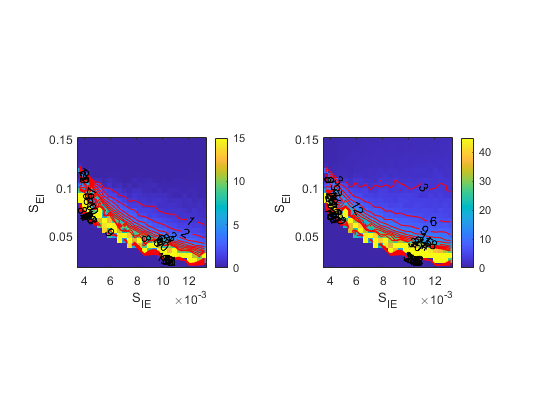

Fr_Plot = Fr_NoFix;
S_IEBound = 8e-3;
DeleteInd = false(size(Fr_Plot));
DeleteInd(:,:,S_IEtest<S_IEBound) = true;
Fr_Plot(Fr_NoFix <=eps & DeleteInd) = nan;

figure('Name','Rough Countour S_EI S_IE')
subplot 121
imagesc(S_IEtest,S_EItest,squeeze(Fr_Plot(1,:,:)))
xlabel('S_{IE}'); ylabel('S_{EI}');
set(gca,'YDir','Normal')
colorbar
caxis([0 15])
axis square
hold on
[C1,h1]= contour(S_IEtest,S_EItest,squeeze(Fr_Plot(1,:,:)),1:1:10,'ShowText','on','color','r');
clabel(C1,h1,'FontSize',10,'Color','k')
axis square
hold off
%axis([min(S_EItest) max(S_EItest) min(S_IEtest) max(S_IEtest)])

subplot 122
imagesc(S_IEtest,S_EItest,squeeze(Fr_Plot(2,:,:)))
xlabel('S_{IE}'); ylabel('S_{EI}');
set(gca,'YDir','Normal')
colorbar
caxis([0 45])
axis square
hold on
[C2,h2]= contour(S_IEtest,S_EItest,squeeze(Fr_Plot(2,:,:)),3:3:30,'ShowText','on','color','r');
clabel(C2,h2,'FontSize',10,'Color','k')
axis square
hold off

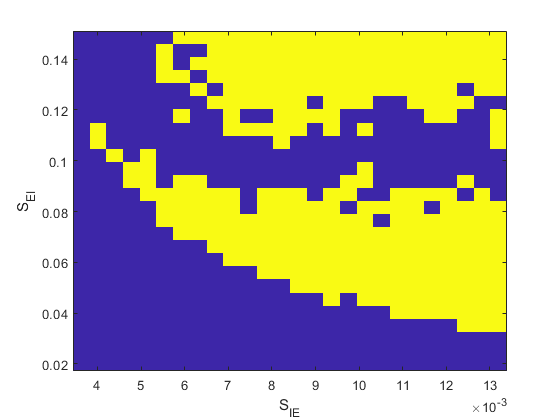

%axis([min(S_EItest) max(S_EItest) min(S_IEtest) max(S_IEtest)])

figure('Name','Convergence')
imagesc(S_IEtest,S_EItest,ConvIndi)
xlabel('S_{IE}'); ylabel('S_{EI}');
set(gca,'YDir','Normal')

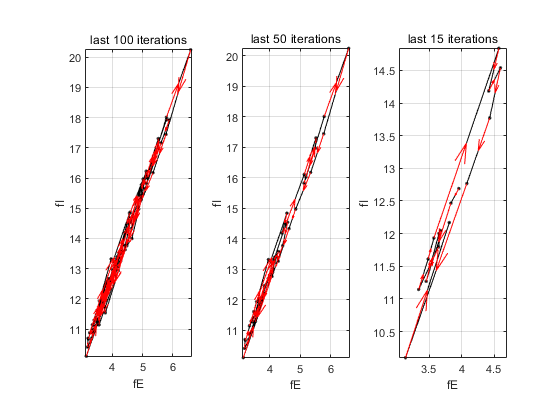

figure('Name','Trajectories-Last')
subplot 131
plot_dir(Fr_NoFixTraj{9,13}(1,end-100:end)',Fr_NoFixTraj{9,13}(2,end-100:end)');
xlabel('fE');ylabel('fI')

title('last 100 iterations')

subplot 132
plot_dir(Fr_NoFixTraj{9,13}(1,end-50:end)',Fr_NoFixTraj{9,13}(2,end-50:end)');
xlabel('fE');ylabel('fI')

title('last 50 iterations')

subplot 133
plot_dir(Fr_NoFixTraj{9,13}(1,end-15:end)',Fr_NoFixTraj{9,13}(2,end-15:end)');
xlabel('fE');ylabel('fI')

title('last 15 iterations')